# Effective Index Method

## Introduction

This script solves for the fundamental TE mode using the Effective Index Method and displays the resulting E-fields in the both the out-of-plane and in-plane directions. 

This method is performed in two steps.

- The slab mode and effective index are found for the out-of-plane cross section for the TE mode.

- The procedure is repeated, except this time, for the in-plane direction. The slab effective index from the first step is used as the input into the second step.

The final result is the effective index of the 2D waveguide. Multiplying these two mode profiles results in the 2D mode profile

## Task

View the field profile for a 500 x 220 nm waveguide.

Use the interactive controls to:

- find the fundamental TE mode effective index at 1500 nm

- modify the wavelength, thickness and width parameters (units: nm) and observe the results

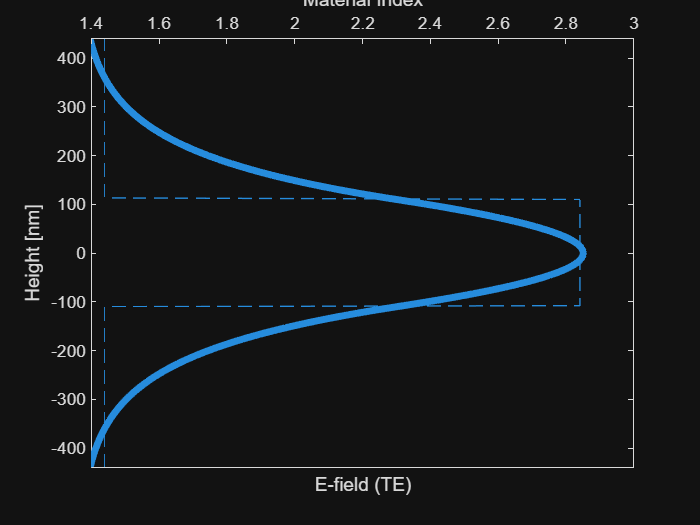

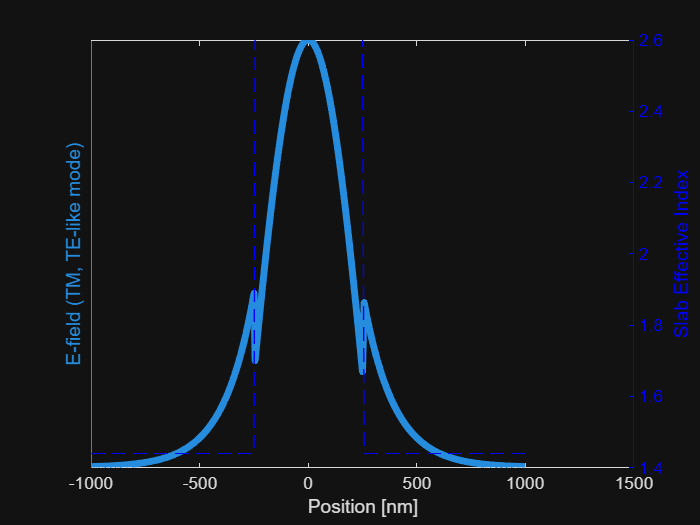

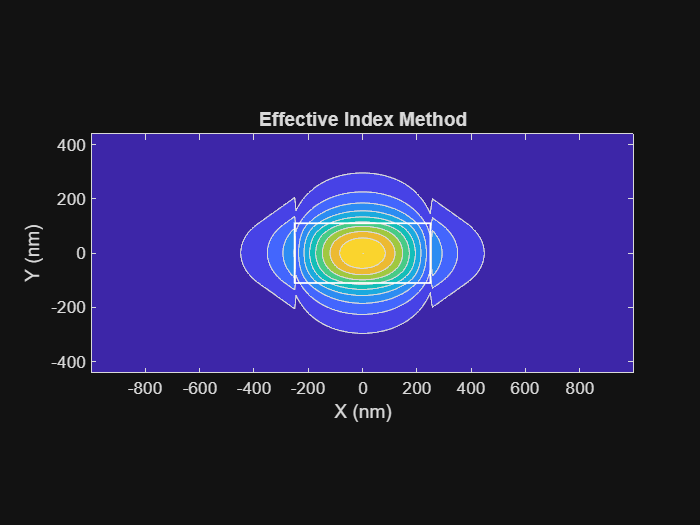

lambda = 1550;   %%% wavelength, [units: nm]
width = 500;   %%% width of the waveguide, [units: nm]
thickness = 220;   %%% thickness of the waveguide, [units: nm]

[neff_TEwg]=wg_EIM_profile (lambda, thickness, width, 0, 3.47, 1.44, 1.44, 100, 2);

Effective index of the waveguide

n_eff = neff_TEwg(1)

n_eff = 2.4844

%% Helper Functions

function [neff_TEwg]=wg_EIM_profile (lambda, t, w, t_slab, n_core, n_clad, n_oxide, pts, M)
% Convert inputs from nm to m
lambda = lambda*1e-9;
t = t*1e-9;
w = w*1e-9;

% find TE (TM) modes of slab waveguide (waveguide core and slab portions):
[nTE,nTM]=wg_1D_analytic (lambda, t, n_oxide, n_core, n_clad);
if gt(t_slab,0)
    [nTE_slab,nTM_slab]=wg_1D_analytic (lambda, t_slab, n_oxide, n_core, n_clad);
else
    nTE_slab=n_clad; nTM_slab=n_clad;
end
[xslab,TE_Eslab,TE_Hslab,TM_Eslab,TM_Hslab]=wg_1D_mode_profile (lambda, t, n_oxide, n_core, n_clad, pts, M);

figure;
plot(TE_Eslab/max(max(TE_Eslab)),xslab*1e9,'LineWidth',4);hold all;
ylabel('Height [nm]');
xlabel('E-field (TE)');
set(gca,'XTick',[]);
axis tight; a=axis; axis ([a(1)*1.1, a(2)*1.1, a(3), a(4)]);
Ax1 = gca; Ax2 = axes('Position',get(Ax1,'Position'));
get(Ax1,'Position');
nx=[nTE_slab(1)*ones(pts,1); nTE(1)*ones(pts-1,1); nTE_slab(1)*ones(pts-1,1)]';
plot (nx, xslab*1e9,  'LineWidth',0.5,'LineStyle','--','parent',Ax2);
a2=axis; axis ([a2(1), a2(2), a(3), a(4)]);
set(Ax2,'Color','none','XAxisLocation','top', 'YTick',[],'TickDir','in');
set(gca,'YAxisLocation','right'); box off;
xlabel('Material Index');

% TE-like modes of the etched waveguide (for fundamental slab mode)
%   solve for the "TM" modes:
[nTE,nTM]=wg_1D_analytic (lambda, w, nTE_slab(1), nTE(1), nTE_slab(1));
neff_TEwg=nTM;
[xwg,TE_E_TEwg,TE_H_TEwg,TM_E_TEwg,TM_H_TEwg]=wg_1D_mode_profile (lambda, w, nTE_slab(1), nTE(1), nTE_slab(1), pts, M);

nx=[nTE_slab(1)*ones(pts,1); nTE(1)*ones(pts-1,1); nTE_slab(1)*ones(pts-1,1)]';
figure%(1); subplot (2,2,3);
% Plot the data on with a left and right axes. Return the axes and line
% objects.
[ax, h1, h2] = plotyy(xwg*1e9, TM_E_TEwg(:,1)/max(max(TM_E_TEwg)), xwg*1e9, nx);
% Set the Xlabel and yLabel of each axes
xlabel('Position [nm]');
ylabel(ax(1),'E-field (TM, TE-like mode)');
ylabel(ax(2), 'Slab Effective Index');
% Change the color of the right axes and the line style of line plot
% associated with that axes.
ax(2).YColor = 'b';
h2.LineStyle = '--';
h2.LineWidth = 0.5;
h2.Color = 'b';
% Set the Line width of the two line plots of the left axes.
h1(1).LineWidth = 4;
% Remove the left Tick labels.
ax(1).YTick = [];
% Set the YLim property so the plots line up.
ax(2).YLim = [1.4, 2.6];
ax(2).YTick = 1.4:0.2:2.6;

% Plot the product of the two fields
figure%(1); subplot (2,2,1);
Exy=TM_E_TEwg(:,1)*(TE_Eslab(1,:));
contourf(xwg*1e9,xslab*1e9,abs(Exy')/max(max(Exy))')
% colormap('jet')
axis equal
xlabel ('X (nm)');
ylabel ('Y (nm)');
A=axis; axis([A(1)+0.4, A(2)-0.4, A(3)+.2, A(4)-0.2]);
title('Effective Index Method');
% Draw the waveguide:
rectangle ('Position',[-w/2,-t/2,w,t]*1e9, 'LineWidth',1, 'EdgeColor','white')
if gt(t_slab,0)
    rectangle ('Position',[-M*w,-t/2,(M-0.5)*w, t_slab]*1e9, 'LineWidth',1, 'EdgeColor','white')
    rectangle ('Position',[w/2,-t/2,(M-0.5),t_slab]*1e9, 'LineWidth',1, 'EdgeColor','white')
end
end

% Helper Functions

function draw_WG_vertical(M)
pP=get(gca,'Position');pPw=pP(3);
pPc=pP(3)/2+pP(1); pP2=pPw/4/M;
annotation ('line',[pPc-pP2,pPc-pP2], [pP(2),pP(4)+pP(2)],'LineStyle','--');
annotation ('line',[pPc+pP2,pPc+pP2], [pP(2),pP(4)+pP(2)],'LineStyle','--');
axis tight; a=axis; axis ([a(1), a(2), a(3)*1.1, a(4)*1.1]);
end

function draw_WG_horiz(M)
pP=get(gca,'Position');pPw=pP(4);
pPc=pP(4)/2+pP(2); pP2=pPw/4/M;
annotation ('line',[pP(1),pP(3)+pP(1)], [pPc-pP2,pPc-pP2],'LineStyle','--');
annotation ('line',[pP(1),pP(3)+pP(1)], [pPc+pP2,pPc+pP2],'LineStyle','--');
axis tight; a=axis; axis ([a(1)*1.1, a(2)*1.1, a(3), a(4)]);
end

function [x, TE_E, TE_H, TM_E, TM_H]= wg_1D_mode_profile (lambda, t, n1, n2, n3, pts, M)
[nTE,nTM,TEparam,TMparam]= wg_1D_analytic(lambda,t,n1,n2,n3);
x1=linspace( -M*t, -t/2, pts);
x2=linspace( -t/2, t/2, pts); x2 = x2(2:end);
x3=linspace( t/2, M*t, pts);  x3 = x3(2:end);
x=[x1 x2 x3];
nx=[n1*ones(pts,1); n2*ones(pts-1,1); n3*ones(pts-1,1)]';
mu0=4*pi*1e-7; epsilon0=8.85e-12; eta=sqrt(mu0/epsilon0); c=3e8; % constants
for i=1:length(nTE)
    h=TEparam(i,2);q=TEparam(i,3); p=TEparam(i,4);
    beta = 2*pi*nTE(i)/lambda;
    C=2*h*sqrt ( 2*pi*c/lambda*mu0 / (beta * (t+1/q+1/p)*(h^2+q^2) ) ); % normalize to 1W
    % n1, n2, n3 regions
    TE_E(i,:)=C*[exp(q*(x1+t/2)), (cos(h*(x2+t/2))+q/h*sin(h*(x2+t/2))), (cos(h*t)+q/h*sin(h*t)).*exp(-p*(x3-t/2))];
end
TE_H=TE_E'.*(nx'*ones(1,length(nTE)))/eta;

for i=1:length(nTM)
    h=TMparam(i,2); q=TMparam(i,3);
    p=TMparam(i,4); qb=n2^2/n1^2*q;pb=n2^2/n3^2*p;
    beta = 2*pi*nTM(i)/lambda;
    temp=(qb^2+h^2)/qb^2 * (t/n2^2 + (q^2+h^2)/(qb^2+h^2)/n1^2/q + ( p^2+h^2)/(p^2+h^2)/n3^2/p) ;
    C=2*sqrt ( 2*pi*c/lambda*epsilon0 / (beta * temp )); % normalize to 1W
    TM_H(i,:)=C*[h/qb*exp(q*(x1+t/2)), (h/qb*cos(h*(x2+t/2))+sin(h*(x2+t/2))), (h/qb*cos(h*t)+sin(h*t)).*exp(-p*(x3-t/2))];
end
TM_E=TM_H'./(nx'*ones(1,length(nTM)))*eta;
end


function [nTE,nTM,TEparam,TMparam]=wg_1D_analytic (lambda, t, n1, n2, n3)
k0 = 2*pi/lambda;
b0 = linspace( max([n1 n3])*k0, n2*k0, 1000);   %k0*n3 less than b less than k0*n2
b0 = b0(1:end-1);
te0=TE_eq(b0,k0,n1,n2,n3,t);
tm0=TM_eq(b0,k0,n1,n2,n3,t);

%TE
intervals=ge(te0,0)-lt(te0,0);
izeros=find(lt(diff(intervals),0));
X0=[b0(izeros); b0(izeros+1)]';
[nzeros,scrap]=size(X0);
for i=1:nzeros
    nTE(i)=fzero(@(x) TE_eq(x,k0,n1,n2,n3,t),X0(i,:))/k0;
    [TEparam(i,1),TEparam(i,2),TEparam(i,3),TEparam(i,4)]= TE_eq(nTE(i)*k0,k0,n1,n2,n3,t);
end
nTE=nTE(end:-1:1);
TEparam=TEparam(end:-1:1,:);

%TM
intervals=ge(tm0,0)-lt(tm0,0);
izeros=find(lt(diff(intervals),0));
X0=[b0(izeros); b0(izeros+1)]';
[nzeros,scrap]=size(X0);
for i=1:nzeros
    nTM(i)=fzero(@(x) TM_eq(x,k0,n1,n2,n3,t),X0(i,:))/k0;
    [TMparam(i,1),TMparam(i,2),TMparam(i,3),TMparam(i,4)]= TM_eq(nTM(i)*k0,k0,n1,n2,n3,t);
end
if gt(nzeros,0)
    nTM=nTM(end:-1:1);
    TMparam=TMparam(end:-1:1,:);
else
    nTM=[];
end
end

function [te0,h0,q0,p0]=TE_eq(b0,k0,n1,n2,n3,t)
h0 = sqrt( (n2*k0)^2 - b0.^2 );
q0 = sqrt( b0.^2 - (n1*k0)^2 );
p0 = sqrt( b0.^2 - (n3*k0)^2 );
% the objective is to find zeroes of te0 and tm0
te0 = tan( h0*t ) - (p0+q0)./h0./(1-p0.*q0./h0.^2);
end

function [tm0,h0,q0,p0]=TM_eq(b0,k0,n1,n2,n3,t)
h0 = sqrt( (n2*k0)^2 - b0.^2 );
q0 = sqrt( b0.^2 - (n1*k0)^2 );
p0 = sqrt( b0.^2 - (n3*k0)^2 );
pbar0 = (n2/n3)^2*p0;
qbar0 = (n2/n1)^2*q0;
tm0 = tan( h0*t ) - h0.*(pbar0+qbar0)./(h0.^2-pbar0.*qbar0);
end